# [Dankai] IPMSM_data_preProcessing.m

% https://kr.mathworks.com/videos/calibrating-optimal-ipmsm-control-using-model-based-calibration-1629787653659.html
% Speed-Based Luts Explaination
% From Below Code
map_data_v1_plot.mlx
% Dankai hu Video  % IPMSM_data_preProcessing.m


Speed-Based LuTs

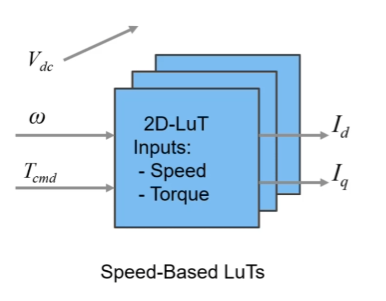

Maximum-Flux-Based LuTs

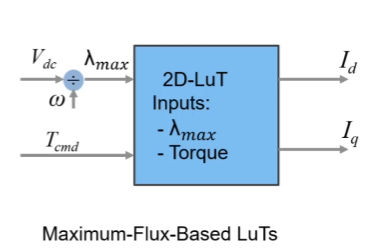

IPMSM_flux_torque_table.xlsx

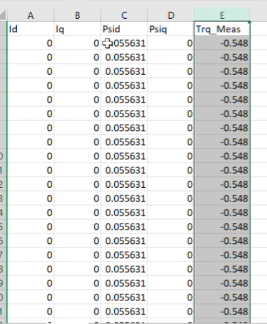

## [Create] Table - 위에 같은 테이블 만들기

% JMAG RT 
  % Efficiency?
% MotorCAD 데이터 형태 - devMBCTeslaSPlaidFromDankai
  % - [satu Map]
  % - [Elec Data (Efficiency or TN curve )
% 연구실 코드 - csv
% [측정 데이터] 데이터 형태  From map_data_v1_plot.mlx (그때그때 다름)

### [MotorCAD] 데이터 형태 - devMBCTeslaSPlaidFromDankai

%% 가져온 데이터형태와 MCAD 데이터형태 차이 구분 
% Current
% 전압
% 자속
% Torque
% elecDataMatPath='Z:\Simulation\LabProj2023BenchMarking\TeslaSPlaid\S_Plaid_M_CAD_1335A_LossModelLSC\Lab\MotorLAB_elecdata.mat'
elecDataMatPath='Z:\01_Codes_Projects\git_fork_emach\tools\SystemSimulationModel\MotorLAB_elecdata.mat'
elecData=load(elecDataMatPath)
%
% SatuMapMatPath='Z:\01_Codes_Projects\git_fork_emach\tools\SystemSimulationModel\DOE\Plaid_A2B2_DegC_20\Lab\SatuMap.mat'
SatuMapMatPath='Z:\01_Codes_Projects\git_fork_emach\tools\SystemSimulationModel\SatuMap.mat'
SatuMapData=load(SatuMapMatPath)

%% Make Input 구조체  
strcmp(elecData.calcType, 'Efficiency Map')
Input.n_max      =max(max(elecData.Speed))    
Input.n_min      =min(min(elecData.Speed))        
Input.Rs         =elecData.Phase_Resistance_DC_at_20C        
Input.p          =rpm2p(elecData.Speed(1,1),elecData.Frequency(1,1));     
Input.Vdc        =unique(elecData.DC_Bus_Voltage)    
Input.Vs_max     =max(max(elecData.Voltage_Phase_Peak))      % Phase or Line?  
Input.Is_max     =max(max(elecData.Stator_Current_Line_Peak))        
Input.test_rpm   =SatuMapData.Speed        
Input.plot_rpm   =SatuMapData.Speed         
Input.Wr_test    = 2 * pi * Input.test_rpm / 60 * Input.p / 2;  % 추가된 변수
Input.Wr_plot    = 2 * pi * Input.plot_rpm / 60 * Input.p / 2;  % 추가된 변수 
%%
n_max    =                Input.n_max    ;
n_min    =                Input.n_min    ;
Rs       =                Input.Rs       ;
p        =                Input.p        ;
Vdc      =                Input.Vdc      ;
Vs_max   =                Input.Vs_max   ;
Is_max   =                Input.Is_max   ;
test_rpm =                Input.test_rpm ;
plot_rpm =                Input.plot_rpm ;
Wr_test  =                Input.Wr_test  ;
Wr_plot  =                Input.Wr_plot  ;

#### 전류 테이블 만들기

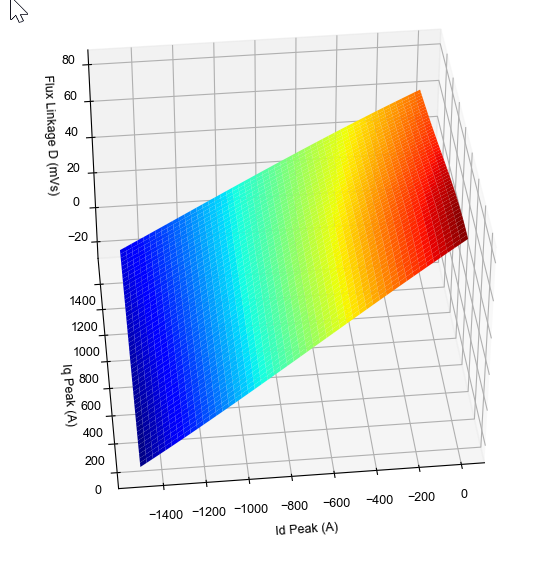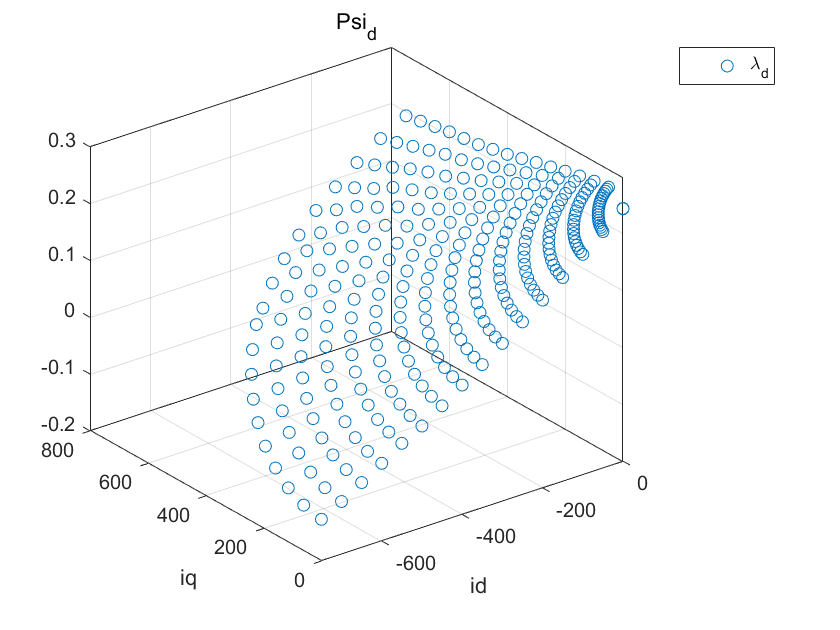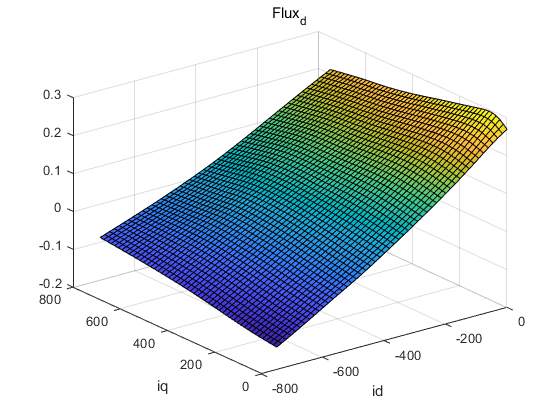

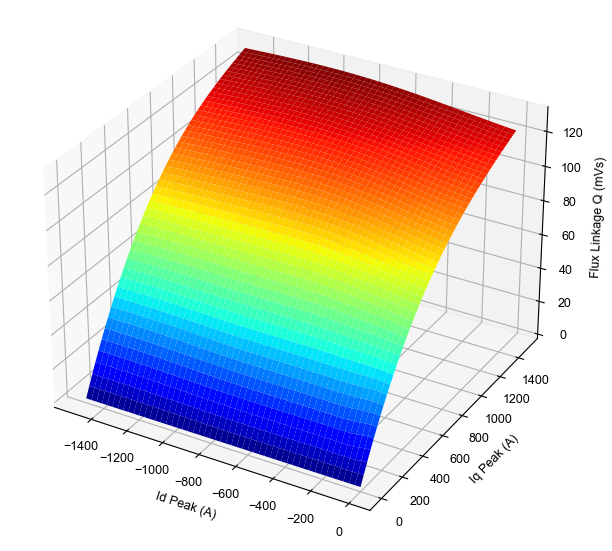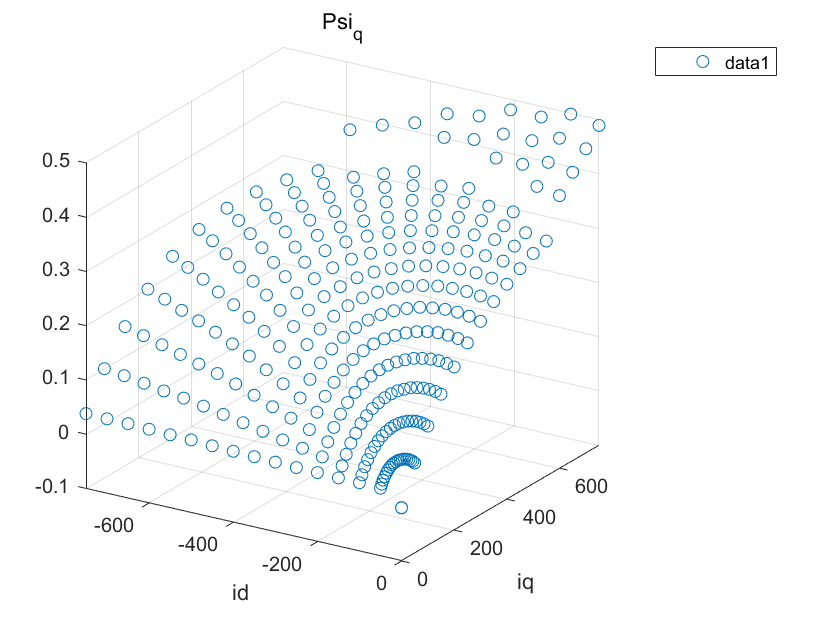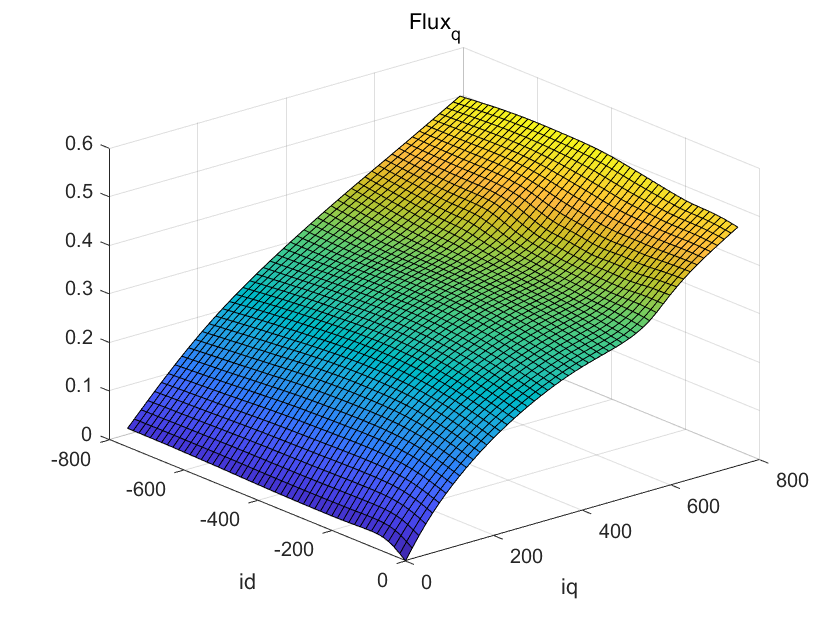

% [I_table,Input] = createCurrentTable(Input);
MotorCADFEA=SatuMapData;
[I_table,Input] = createCurrentTableMCAD(SatuMapData);

## VisualizeFluxSurface

VisualizeFluxSurfaceTeslaSPlaid


%figure
hold on
figure(1)
surf(MotorCADFEA.Id_Peak,MotorCADFEA.Iq_Peak,MotorCADFEA.Flux_Linkage_D);
%figure
figure(2)
hold on
surf( MotorCADFEA.Id_Peak,MotorCADFEA.Iq_Peak,MotorCADFEA.Flux_Linkage_Q);


## createCurrentTableMCAD

% % [I_table,Input] = createCurrentTableMCAD(Input);
% i_d=MotorCADFEA.Id_Peak;
% i_q=MotorCADFEA.Iq_Peak;
% % [I_pk,phase_advance]=dq2pkBeta(i_d,i_q);
% I_pk=MotorCADFEA.Stator_Current_Line_Peak
% phase_advance=MotorCADFEA.Phase_Advance
% MotorCADFEA.Voltage_Line_Peak
% 
% scatter(I_pk,phase_advance)
% 
% %%
% id_axis=linspace(-Is_max,0,50);
% iq_axis=linspace(0,Is_max,50);
% lamda_d=gridfit(I_table.Id,I_table.Iq,I_table.Lamda_ds,id_axis,iq_axis);
% lamda_q=gridfit(I_table.Id,I_table.Iq,I_table.Lamda_qs,id_axis,iq_axis);
% Trq_dq=gridfit(I_table.Id,I_table.Iq,I_table.TorqueDq,id_axis,iq_axis);


I_table = table(flatten_Id_Peak, flatten_Iq_Peak, flatten_Id_Peak, flatten_Iq_Peak);
I_table.Properties.VariableNames = {'Iph', 'phase_advance', 'Id', 'Iq'};
% I_table = sortrows(I_table,'phase_advance','ascend');
% I_table = sortrows(I_table,'Iph','ascend');

#### [TC]전압 테이블 

I_table = createVoltageTable(I_table);
% I_table = addvars(I_table, Vds_t, Vqs_t, Vabs_s, 'after', 'Iq');


#### [TC]자속맵 - 토크, 전압 테이블로부터 변환

I_table = createFluxMaps(I_table,Input);

flatten_lamda_d = MotorCADFEA.Flux_Linkage_D(:);
flatten_lamda_q = MotorCADFEA.Flux_Linkage_Q(:);
% 결과를 I_table에 추가
I_table.Lamda_ds = flatten_lamda_d;
I_table.Lamda_qs = flatten_lamda_q;

#### [TC]토크맵 비교 - 맵데이터

I_table = createTorqueDqMap(I_table,Input);

### [TC][Plot] Flux and Torque in dq plane

% 위 함수들을 호출하여 그래프 생성
Id = I_table.Id;
Iq = I_table.Iq;
Lamda_ds = I_table.Lamda_ds;
Lamda_qs = I_table.Lamda_qs;
torque3_map = I_table.TorqueDq;
runPlots(Id, Iq, Lamda_ds, Lamda_qs, torque3_map);
% runPlots(Id, Iq, Lamda_ds, Lamda_qs, torque3_map, torque2_calc, torque_error);
% opts.VariableNames = ["Id", "Iq", "Psid", "Psiq", "Trq Meas"] ;
% 속도는 ? - 역산가능 why? id,iq 알고 torque알고, Psid, Psiq 아니까 전압은 예상가능?
% FEM 데이터로 해보자 
% KU LUT는?
% 

## [Dankai] IPMSM_data_preProcessing.m

### [Convert] unfitted raw data vectors into matrix through gridfit and visually check plots

Is_max=max(flatten_Iq_Peak)
id_axis=linspace(-Is_max,0,101);

iq_axis=linspace(0,Is_max,101);
flatten_Id_Peak = MotorCADFEA.Id_Peak(:);
flatten_Iq_Peak = MotorCADFEA.Iq_Peak(:);
flatten_lamda_d = MotorCADFEA.Flux_Linkage_D(:);
flatten_lamda_q = MotorCADFEA.Flux_Linkage_Q(:);
lamda_d=gridfit(flatten_Id_Peak,flatten_Iq_Peak,flatten_lamda_d,id_axis,iq_axis);
lamda_q=gridfit(flatten_Id_Peak,flatten_Iq_Peak,flatten_lamda_q,id_axis,iq_axis);

% Trq_calc=Trq_dq;

%figure
hold on
figure(1)
surf(id_axis,iq_axis,lamda_d);
%figure
hold on
figure(2)
surf(id_axis,iq_axis,lamda_q);
%% Torque
Trq_dq=gridfit(I_table.Id,I_table.Iq,I_table.TorqueDq,id_axis,iq_axis);
figure(3)
surf(id_axis,iq_axis,Trq_dq);
Trq_calc=Trq_dq;


### [Rearrange] ([Generate] csv data file) data to torque-speed operating points

#### Step 1 calculate the torque contour

T_step=[1 3 6 10 linspace(15,max(max(abs(Trq_calc))),100)];
hold on
figure(3)
T_contour=contour3(id_axis,iq_axis,Trq_calc,T_step);

#### Step 2, define the speed steps

[~, Input] = createCurrentTable()
n_min=Input.n_min;
n_max=Input.n_max;
n=(n_min:250:n_max)';

#### Step 3, re-arrange data to torque-speed operating points


T_start=1;
data=[];

while T_start<length(T_contour)
    T_stop=T_start+T_contour(2,T_start);

    %generate [Trq,Id,Iq]
    data_temp=[repelem(T_contour(1,T_start),T_contour(2,T_start))' T_contour(1,T_start+1:T_stop)' T_contour(2,T_start+1:T_stop)']

    % ***** Adding contour downsample code here ****** %
    % Downsample by a factor of 5 %

    data_downsample =downsample(data_temp,5);
    if ( data_downsample(end,2)~=data_temp(end,2))
        data_temp =[data_downsample; data_temp(end,:)];
    else
        data_temp=data_downsample;
    end

    data=[data; repmat(data_temp,[length(n),1]) repelem(n,length(data_temp(:,1)))]; %[Trq, Id,Iq,n]
    T_start=T_stop+1;
end

#### Step 4, Make MBC data (Maximum Current, PhisD, Phiq,Vd,Vq, Vs)


Is=sqrt(data(:,2).^2+data(:,3).^2); % calculated maximum current
flux_d=interp2(id_axis,iq_axis,lamda_d,data(:,2),data(:,3));
flux_q=interp2(id_axis,iq_axis,lamda_q,data(:,2),data(:,3));

flux=sqrt(flux_d.^2+flux_q.^2);
we=2*pi.*data(:,4).*Input.p/2./60;
% calculated modulated voltage
vd=Input.Rs.*data(:,2)-we.*flux_q;
vq=Input.Rs.*data(:,3)+we.*flux_d;
Vs=sqrt(vd.^2+vq.^2); %modulation voltage
IPMSM_MBCData=[data Vs Is]; %[Trq id iq n Vs Is] % Is:peak

%% Check By Visual
hold on
figure(3)
scatter3(IPMSM_MBCData(:,2),IPMSM_MBCData(:,3),IPMSM_MBCData(:,1));
% scatter3(IPMSM_MBCData(:,2),IPMSM_MBCData(:,3),IPMSM_MBCData(:,6));

### [Export] csv data file

header ={'Trq' 'Id' 'Iq' 'n' 'Vs' 'Is'};
xlswrite('.\IPMSM_MBCData.xlsx',header,'sheet1');
xlswrite('.\IPMSM_MBCData.xlsx',IPMSM_MBCData,'sheet1','A2');
clearvars -except IPMSM_MBCData Is_max Vs_max

## [MBCFittingTool] - Modeling with Gaussian Model

cage
mbcmodel
mbcconfig


## [MBCCalibration] - Idq Calibration 